# **RRA**

# **Lab11 (Parteneriat cu laburile scrise de PETrascu)**

## Problema de regalre $\mathcal{H}_{\infty}$(o sa fac si o recaliptulare la calcularea normei $\mathcal{H}_{\infty}
$ si $\mathcal{L}_{\infty}
$)

Norma $\mathcal{H}_{\infty}$ :$\sup_{w\in \mathbb{R}} \bar{\sigma} \left(G\left(\mathrm{jw}\right)\right)$, unde $\bar{\sigma}$ este valoarea maxima singulara a matricii de transfer $G\left(s\right)$. Noi in cazul MIMO **nu avem valori proprii, cu functii proprii si practic ne uitam la fiecare functie si luam doar maximul.**

La $\mathcal{L}_{\infty}
$: $\sup_{t\ge 0} \left(\max_i |e_i \left(t\right)|\right)$.

Ideea e ca una se uita in frecventa, alta in timp.

## Acum sa trecem la problema noastra (revizuieste RRA_lab10 pentru problema $\mathcal{H}_2$)

La baza este aceeasi problema ca $\mathcal{H}_2$. 

Fie sistemul generalizat $\left\lbrace \begin{array}{l}
\dot{x} =\mathrm{Ax}+B_1 u_1 +B_2 u_2 \\
y_1 =C_1 x+D_{11} u_1 +D_{12} u_2 \\
y_2 =C_2 x+D_{21} u_1 +D_{22} u_2 
\end{array}\right.$

Reprezentarea pe stare arata asa: $T=\left\lbrack \begin{array}{ccc}
A & B_1  & B_2 \\
C_1  & D_{11}  & D_{12} \\
C_2  & D_{21}  & D_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
T_{11}  & T_{12} \\
T_{21}  & T_{22} 
\end{array}\right\rbrack$ (aceeasi imparteala)

Problema optimala $\mathcal{H}_{\infty}$ arata asa: $\min_{K \text{ stabil}} ||TLFi(T,K)||_{\infty}$, unde $TLFI(T,K)=T_{cl}$ (In slide-urile de curs este notat $T_{y_1 u_1 }$)

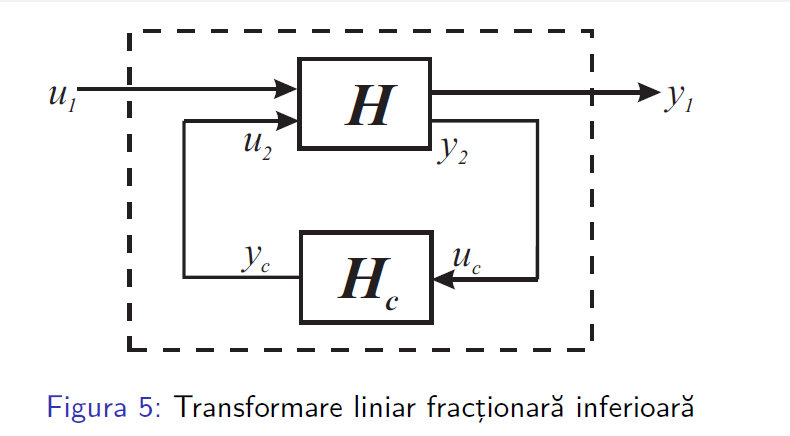


$$TLFi(T,K)=T_{11} + T_{12}K(I-T_{22}K)^{-1}T_{21}$$


Fie $K=\left\lbrack \begin{array}{cc}
A_K  & B_K \\
C_K  & D_k 
\end{array}\right\rbrack$. Trebuie sa existe ${\left(I-T_{22} K\right)}^{-1}$. Pentru a asigura buna definire, trebuie ca $\left\lbrack \begin{array}{cc}
I & -D_K \\
-D_{22}  & I
\end{array}\right\rbrack$ sa fie inversabil. Aici o smecherie: nu conteaza daca $D_K \;\mathrm{si}\;D_{22}$ sunt cu + sau -.

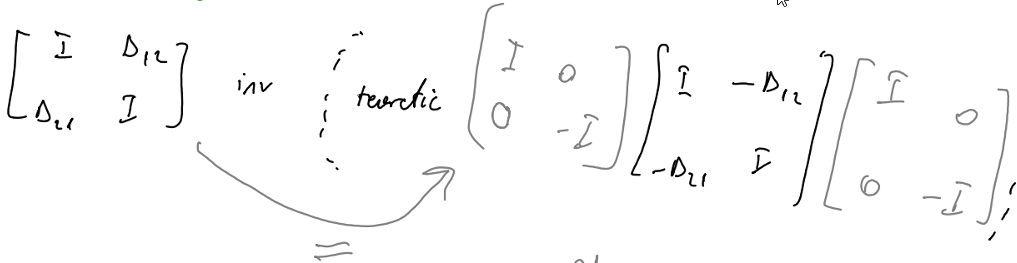

Sa zicem reprezentarea pe stare $TLFi(T,K)=T_{cl}=$$\left\lbrack \begin{array}{cc}
A_{\mathrm{cl}}  & B_{\mathrm{cl}} \\
C_{\mathrm{cl}}  & D_{\mathrm{cl}} 
\end{array}\right\rbrack$

### Acum o sa discutam despre problema $\mathcal{H}_{\infty}
$ suboptimala.

Fie un sismte $T$ si un $\gamma >0$. Aceasta problema consta in gasirea tuturor regulatoarelor $K$pentur care $T_{\mathrm{cl}} =\mathrm{TLFi}\left(T,K\right)$ este biene definit in sens strict, intern stabil $\left(\Lambda \left(A_{\mathrm{cl}} \right)\in {\mathbb{C}}_- \right)$ (si se numeste un compensator stabilizator) si marginta in norma $\mathcal{H}_{\infty}
$. adica $||T_{\mathrm{cl}} ||_{\infty } <\gamma$ ( si se numeste un compensator $\gamma -\mathrm{contraceptiv}$)

**Care e faza cu acel **$\gamma$**? **Ideea la el e asa: minimizarea este o problema extrem de urata si crunta matematic, asadar facem problema suboptimala $\gamma$. Adica luam gamma realtiv aleator si ne rugam sa dea ceva ok (loterie in a way). Mai avem o problema: Cand ne apropiem cu $\gamma$ de $\gamma_{\mathrm{optim}}$, inversele de matrici devin prost conditionat numeric si nu ne mai putem crede in ce ne zice matlab.

Acest fel de problema nu are solutie unica, ci o clasa intreaga de regualtoare pe aceleasi ipoteze de regularitate.

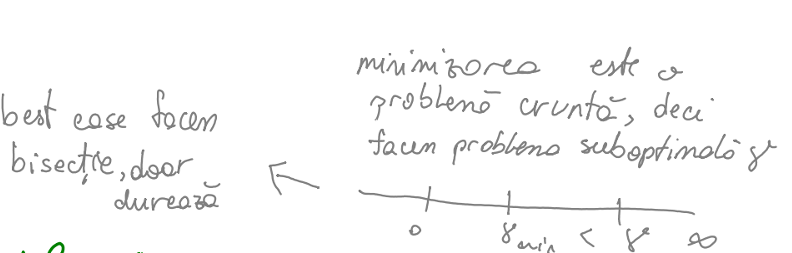

Precum la problema ${\mathcal{H}}_2$, facem si aici urmatoarele ipoteze:

- $D_{22} =0$. Daca nu, $\tilde{T} -T-\left\lbrack \begin{array}{cc}
0 & 0\\
0 & D_{22} 
\end{array}\right\rbrack$, scoatem pe $\tilde{K}$ si scriem $K=\tilde{K} {\left(I+D_{22} \tilde{K} \right)}^{-1}$(la problema ${\mathcal{H}}_2$ dracenia asta era bine conditionata. Acum nu mai avem garantie ca e, DAAAAR in general clasa de $\tilde{K}$ se gaseste unu sa mearga)

- $\gamma =1$. Daca $\gamma \not= 1$, atunci $||\mathrm{TLFi}\left(T,K\right)||_{\infty } <\gamma \Leftrightarrow ||\mathrm{TLFi}\left(T,K\right)\frac{1}{\gamma }||_{\infty } <1$$\Leftrightarrow ||\frac{1}{\gamma }\left(T_{11} +T_{12} {K\left(I-T_{22} K\right)}^{-1} T_{21} \right)||_{\infty } <1$. Ideea la baza este ca facem o scalare, si anume $T_{\gamma } =\left\lbrack \begin{array}{cc}
\frac{1}{\gamma }T_{11}  & \frac{1}{\sqrt{\gamma }}T_{12} \\
\frac{1}{\sqrt{\gamma }}T_{21}  & T_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A & \frac{1}{\sqrt{\gamma }}B_1  & B_2 \\
\frac{1}{\sqrt{\gamma }}C_1  & \frac{1}{\gamma }D_{11}  & \frac{1}{\sqrt{\gamma }}D_{12} \\
C_2  & \frac{1}{\sqrt{\gamma }}D_{21}  & D_{22} 
\end{array}\right\rbrack$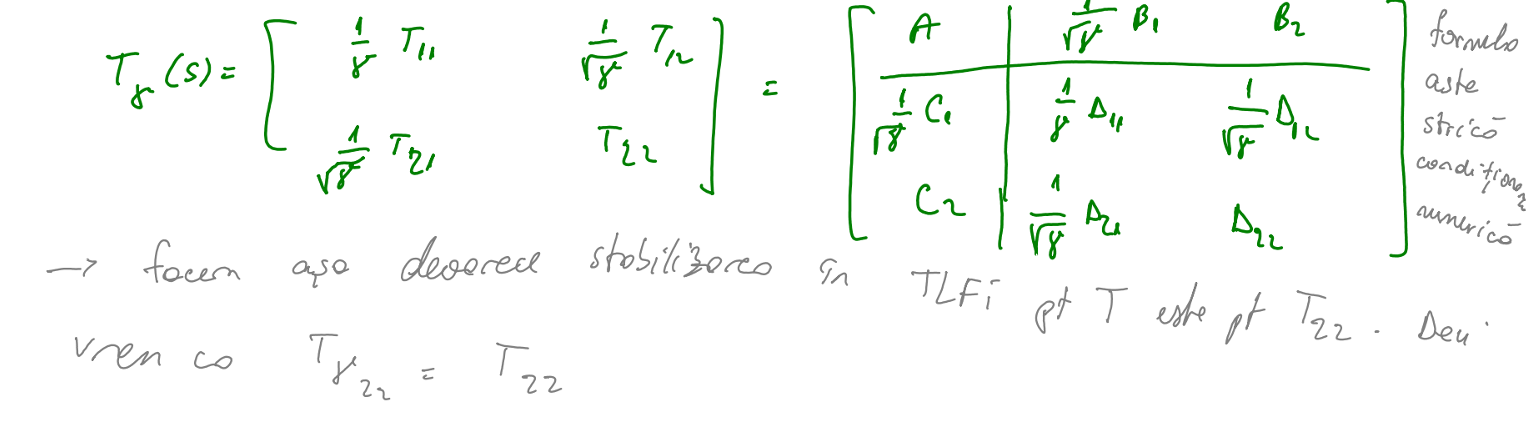

Bine, putem scrie $\frac{1}{\gamma }\mathrm{TLFi}\left(T,K\right)=\mathrm{TLFi}\left(T_{\gamma } ,K\right)$. Se prefera a doua pentur ca este ma simpla. IN cartea lui Oara, se face prima varianta, adica scalarea lui $T_{22} \;\mathrm{si}\;K$. Este mai greu asa.

Fie sistemu nostru $T$ cu 2 triplete Popov asociate:$\left\lbrace \begin{array}{l}
\Sigma_{12} =\left(A;B_2 ;\left\lbrack \begin{array}{cc}
C_1^T C_1  & C_1^T D_{12} \\
D_{12}^T C_1  & D_{12}^T D_{12} 
\end{array}\right\rbrack \right)\\
\Sigma_{21} =\left(A^T ;C_2^T ;\left\lbrack \begin{array}{cc}
B_1 B_1^T  & B_1 D_{21}^T \\
D_{21} B_1^T  & D_{21} D_{21}^T 
\end{array}\right\rbrack \right)
\end{array}\right.$.* Practic astea sunt factorilzarile inner-outer pentru *$T_{12}$* si co-inner-outer pentru *$T_{21}$. La $\Sigma_{12}$ are sens forma. La $\Sigma_{21}$ pare mai ciudatica. De ce? Noi stim 2 chestii: $\left\lbrace \begin{array}{l}
\left(C_2 ,A\right)\;\mathrm{detectabil}\Rightarrow \left(A^T ,C_2^T \right)\;\mathrm{stabilizabil}\\
\Sigma =\left(A;B;\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack \right),\mathrm{unde}\;Q=C^T C,R=D^T D\;\mathrm{si}\;L=C^T D
\end{array}\right.$. Practic la tripletul Popov $\Sigma_{21}$, $A=A^T \;\mathrm{si}\;B=C_2^T$. Asta inseamna ca $C=B_1^T \;\mathrm{si}\;D=D_{21}^T$ si se inlocuiesc in matrice.

Pornind de la cele 2 triplete Popov, facem urmatoarele ipoteze de regularitate:

        **H1)** Stim deja ca $\left(A,B_2 \right)$ stabilizabil. Totodata, mai presupunem ca $R_{12} =D_{12}^T D_{12} >0$ are rang integ pe coloane si ca matricea $\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_2 \\
C_1  & D_{12} 
\end{array}\right\rbrack$ are rang intreg pe coloane, adica $\mathrm{rang}\;\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_2 \\
C_1  & D_{12} 
\end{array}\right\rbrack =n+m_2$, $\forall w\in \mathbb{R}$ (coloane aici). Prin asta se indeplinesc toate ipotezele de factorizare inner-outer.

        **H2)** Stim deja ca $\left(C_2 ,A\right)$ detectabil Totodata, mai presupunem ca $R_{21} =D_{21} D_{21}^T >0$ are rang integ pe linii si ca matricea $\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_1 \\
C_2  & D_{21} 
\end{array}\right\rbrack$ are rang intreg pe linii, adica $\mathrm{rang}\;\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_1 \\
C_2  & D_{21} 
\end{array}\right\rbrack =n+p_2$, $\forall w\in \mathbb{R}$ (linii aici)

La **H1) si H2)** scalarea cu $\frac{1}{\gamma }$ NU afecteaza rangul si inversabilitatea. Totodata, in slide-irle de curs, matricile sunt aceleasi, doar ca sunt cu minus

## Acum vorbim de Teorema Centrala (Teorema Redheffer pare pe curs)

Sa ma fereasca Dumnezeu. De aici devine nasol

Pentru $T$ considerat in **H1) si H2)**, avem urmatoarele 2 triplete Popov:

$\left\lbrace \begin{array}{l}
\Sigma_c =\left(A;\left\lbrack \begin{array}{cc}
B_1  & B_2 
\end{array}\right\rbrack ;\left\lbrack \begin{array}{cc}
Q_c  & L_c \\
L_c^T  & R_c 
\end{array}\right\rbrack \right)\\
\Sigma_o =\left(A^T ;\left\lbrack \begin{array}{c}
C_1 \\
C_2 
\end{array}\right\rbrack ;\left\lbrack \begin{array}{cc}
Q_o  & L_o \\
L_o^T  & R_o 
\end{array}\right\rbrack \right)
\end{array}\right.$, unde

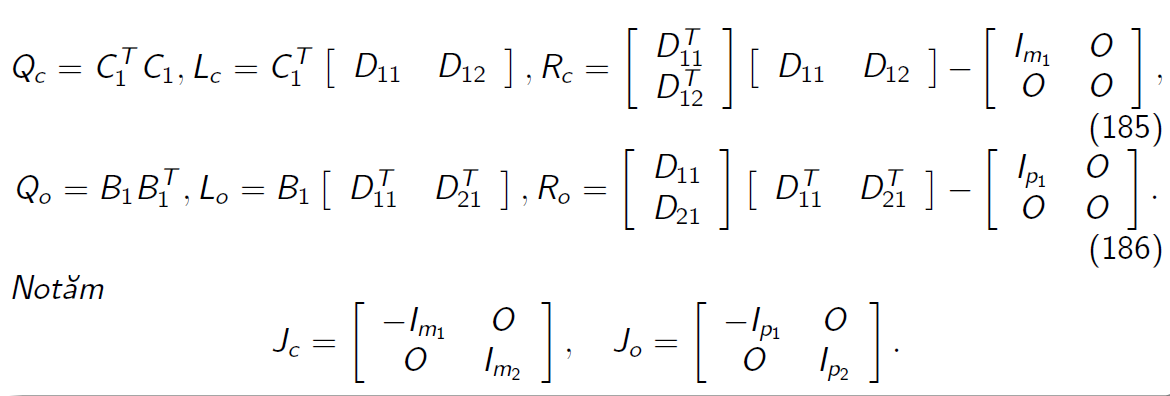

Atunci avem:

## I)

### Problema are solutie daca si numai daca

        **C1)** $\mathrm{SKYP}\left(\Sigma_c ,J_c \right)$ are solutie stabilizatoare $\left(X,V_c ,W_c \right)=\left(X,\left\lbrack \begin{array}{cc}
V_{c_{11} }  & 0\\
V_{c_{21} }  & V_{c_{22} } 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
W_{\mathrm{c1}} \\
W_{\mathrm{c2}} 
\end{array}\right\rbrack \right),\mathrm{cu}\;X\ge 0$

        **C2) **$\mathrm{SKYP}\left(\Sigma_o ,J_o \right)$ are solutie stabilizatoare $\left(Y,V_o ,W_o \right)=\left(Y,\left\lbrack \begin{array}{cc}
V_{o_{11} }  & 0\\
V_{o_{21} }  & V_{o_{22} } 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
W_{\mathrm{o1}} \\
W_{\mathrm{o2}} 
\end{array}\right\rbrack \right),\mathrm{cu}\;Y\ge 0$

        **C3)** Raza spectrala a matricei XY este strict subunitara, adica $\rho \left(\mathrm{XY}\right)<1$

Daca conditiile **C1-3)** sunt indeplinite, atunci exista regulator stabilizator

## II) (o sa sune ciudat)

Presupunem ca **C1)** tine. Fie $J_{\times } =\left\lbrack \begin{array}{cc}
-I_{\mathrm{m2}}  & 0\\
0 & I_{\mathrm{p2}} 
\end{array}\right\rbrack$, si tripletul Popov $\Sigma_{\times } =\left(A^T +F_1^T B_1^T ;\left\lbrack \begin{array}{cc}
-F_2^T V_{\mathrm{c22}}^T  & C_2^T +F_1^T D_{21}^T 
\end{array}\right\rbrack ;\left\lbrack \begin{array}{cc}
Q_{\times }  & L_{\times } \\
L_{\times }^T  & R_{\times } 
\end{array}\right\rbrack \right)$, unde $\left\lbrack \begin{array}{c}
F_1 \\
F_2 
\end{array}\right\rbrack$ este reactia stabilizatoare lui $\mathrm{SKYP}\left(\Sigma_c ,J_c \right)$ si 

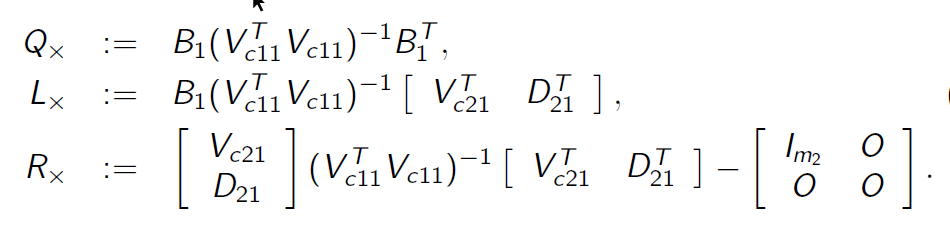

Atunci probema are solutie $\Leftrightarrow$ **C1)** are loc si conditia

        **C4)** $\mathrm{SKYP}\left(\Sigma_{\times } ,J_{\times } \right)$ are solutie stabilizatoare $\left(Z,V_{\times } ,W_{\times } \right)=\left(Z,\left\lbrack \begin{array}{cc}
V_{\times 11}  & 0\\
V_{\times 21}  & V_{\times 22} 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
W_{\times 1} \\
W_{\times 2} 
\end{array}\right\rbrack \right)$ cu $Z\ge 0$. Mai mult, $Z={Y\left(I-\mathrm{XY}\right)}^{-1}$

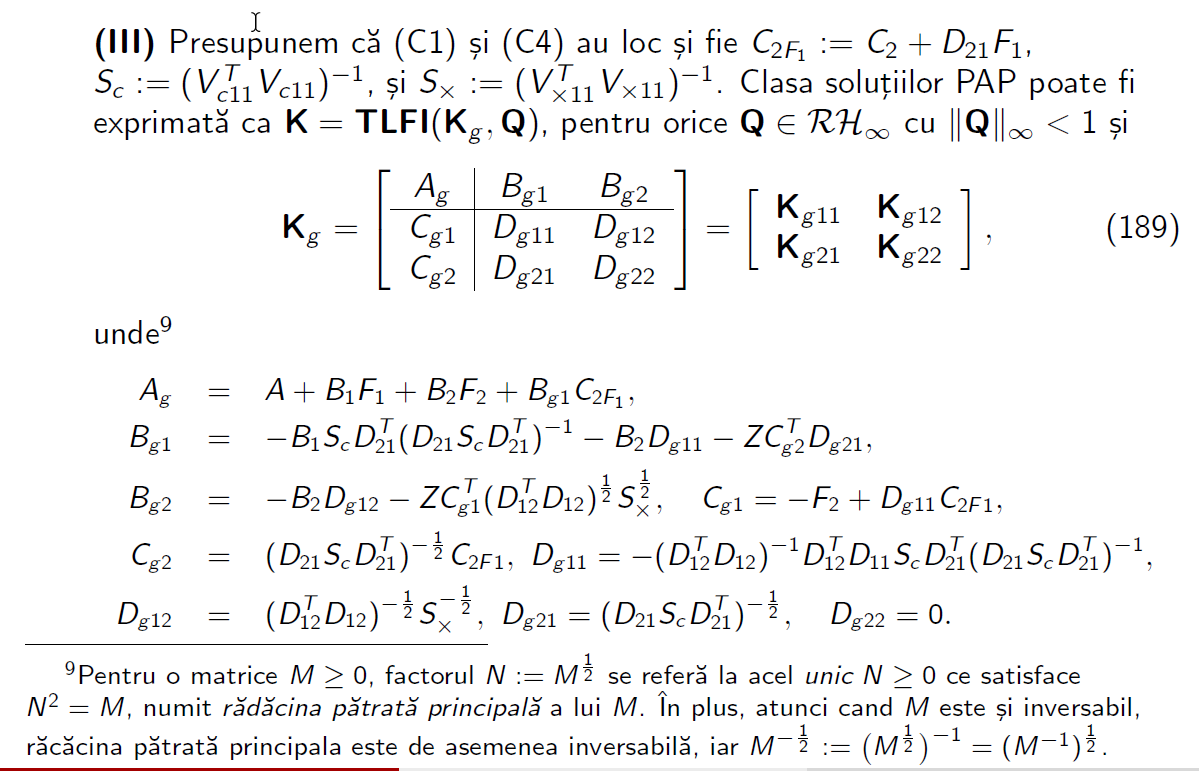

Asta e direct bataie de joc, las-o drq

## Sa intram in laborator (te pwp Gabi)

clear
close all
clc

A = randn(4);
A = eye(4) + randn(4); % antistabil din prima
% m1 = 3;
% p1 = 3;
% m2 = 2;
% p2 = 2;
B1 = randn(4 ,3);
B2 = randn(4, 2);
C1 = randn(3 ,4);
C2 = randn(2, 4);
D11 = randn(3);
D12 = randn(3, 2);
D21 = randn(2, 3);
D22 = randn(2);

Ca sa nu ne faca aleator asta

tzero(A,B2,[],[]) % controlabil


ans =

  0×1 empty double column vector



tzero(A,[],C2,[])  % observabil


ans =

  0×1 empty double column vector



rank(D12)

ans = 2

rank(D21)

ans = 2

tzero(A,B2,C1,D12) % nu sunt 0-uri pe axa imaginara la T12


ans =

  0×1 empty double column vector



tzero(A,B1,C2,D21) % nu sunt 0-uri pe axa imaginara la T21


ans =

  0×1 empty double column vector



Alta sectiune (aleg gamma)

gamma = 100;
B1s = B1 / sqrt(gamma);
C1s = C1 / sqrt(gamma);
D11s = D11 / gamma;
D12s = D12 / sqrt(gamma);
D21s = D21 / sqrt(gamma);

Alta sectiune (aici vad partea de scalare daca e ok). Faza aici este sa vedem ca acest $\gamma$ nu a introdus ceva instabilitate numerica

rank(D12s)

ans = 2

rank(D21s)

ans = 2

tzero(A,B2,C1s,D12s) % nu sunt 0-uri pe axa imaginara la T12


ans =

  0×1 empty double column vector



tzero(A,B1s,C2,D21s) % nu sunt 0-uri pe axa imaginara la T21


ans =

  0×1 empty double column vector



Partea 1 din teroema (SKYP de c, adica prima solutie EMAR)

EMAR are solutie cu ICARE sau cu SKYP. Ca sa verif SKYP ne folosim de solutia ICARE ca au oricum aceeasi solutie

Vad ca $J_c =\left\lbrack \begin{array}{cc}
-I_{\mathrm{m1}}  & 0\\
0 & I_{\mathrm{m2}} 
\end{array}\right\rbrack$

J_c = blkdiag(-eye(3),eye(2)) % m1 si m2

J_c =     -1     0     0     0     0
     0    -1     0     0     0
     0     0    -1     0     0
     0     0     0     1     0
     0     0     0     0     1


Solutia EMAR aici, cu $B_c =\left\lbrack \begin{array}{cc}
B_1  & B_2 
\end{array}\right\rbrack$,$Q_c =C_1^T C_1$,$R_c =\left\lbrack \begin{array}{cc}
D_{11}^T D_{11} -I & D_{11}^T D_{12} \\
D_{12}^T D_{11}  & D_{12}^T D_{12} 
\end{array}\right\rbrack$,$L_c =C_1^T \left\lbrack \begin{array}{cc}
D_{11}  & D_{12} 
\end{array}\right\rbrack$. Aici adaugam scalarile

[X,F] = icare(A, [B1s B2], C1s' * C1s, ...
 [ D11s' * D11s - eye(3), D11s' * D12s;  D12s' * D11s, D12s' * D12s],  ...
 C1s' * [D11s, D12s] ); % m1 aici
eig(X) % verificam ca X este pozitiv semi-definit

ans =     0.0005
    0.0277
    0.5467
  147.1646


Daca X nu este pozitiv semidefinit, atunci nu e solutie, deci $\gamma$ prea mic

F = -F; % vrem reactie pozitiva

Stim ca $\mathrm{SKPY}\left(\Sigma_c ,J_c \right)=\left(X,\left\lbrack \begin{array}{cc}
V_{c_{11} }  & 0\\
V_{c_{21} }  & V_{c_{22} } 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
W_{c_1 } \\
W_{c_2 } 
\end{array}\right\rbrack \right)$. Acum stam si calculam aici:

### SKYP general:

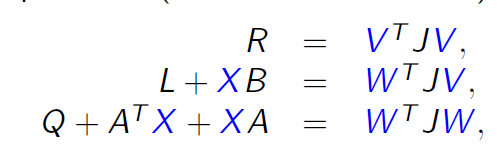

Reatasez $R_c =\left\lbrack \begin{array}{cc}
D_{11}^T D_{11} -I & D_{11}^T D_{12} \\
D_{12}^T D_{11}  & D_{12}^T D_{12} 
\end{array}\right\rbrack$ si $V_c =\left\lbrack \begin{array}{cc}
V_{c_{11} }  & 0\\
V_{c_{21} }  & V_{c_{22} } 
\end{array}\right\rbrack ,W_c =\left\lbrack \begin{array}{c}
W_{c_1 } \\
W_{c_2 } 
\end{array}\right\rbrack$

O sa am: $\left\lbrack \begin{array}{cc}
D_{11}^T D_{11} -I & D_{11}^T D_{12} \\
D_{12}^T D_{11}  & D_{12}^T D_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
V_{c_{11} }^T  & V_{c_{21} }^T \\
0 & V_{c_{22} }^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
-I_{\mathrm{m1}}  & 0\\
0 & I_{\mathrm{m2}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
V_{c_{11} }  & 0\\
V_{c_{21} }  & V_{c_{22} } 
\end{array}\right\rbrack$$\Rightarrow$$\left\lbrack \begin{array}{cc}
D_{11}^T D_{11} -I & D_{11}^T D_{12} \\
D_{12}^T D_{11}  & D_{12}^T D_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{-V}_{c_{11} }^T  & V_{c_{21} }^T \\
0 & V_{c_{22} }^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
V_{c_{11} }  & 0\\
V_{c_{21} }  & V_{c_{22} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-V_{c_{11} }^T V_{c_{11} } +V_{c_{21} }^T V_{c_{21} }  & V_{c_{21} }^T V_{c_{22} } \\
V_{c_{22} }^T V_{c_{21} }  & V_{c_{22} }^T V_{c_{22} } 
\end{array}\right\rbrack$


$$D_{12}^T D_{12} =V_{c_{22} }^T V_{c_{22} }$$


Vc22 = chol(D12s' * D12s,'lower')'

Vc22 =     0.2231    0.1922
         0    0.2077



$$D_{12}^T D_{11} =V_{c_{22} }^T V_{c_{21} }$$


Vc21 =  (Vc22') \ (D12s' * D11s);


$$D_{11}^T D_{11} -I=-V_{c_{11} }^T V_{c_{11} } +V_{c_{21} }^T V_{c_{21} }$$


Vc11 = chol (Vc21' * Vc21 + eye(3) - D11s' * D11s, 'lower'); % daca nu da semipozitiv-definita, neinversabila
Wc = - [Vc11, zeros(3,2); Vc21, Vc22] * F;
Wc1 = Wc(1:3, :)

Wc1 =    15.6798    2.3566    5.0148   -1.6018
    5.1502    0.7361    1.6114   -0.4894
    8.1992    1.2567    2.6478   -0.8577


Wc2 = Wc(4:5, :)

Wc2 =    -2.0855   -0.1156   -0.2565    0.1735
   31.0691    4.4426    9.5323   -3.0645


norm ( C1s' * [ D11s, D12s] +  X * [B1s B2] - Wc' * J_c * [Vc11, zeros(3,2); Vc21, Vc22])

ans = 8.3739e-08

Alta sectiune (SKYP la o)


$$J_o -\left\lbrack \begin{array}{cc}
-I_{\mathrm{p1}}  & 0\\
0 & I_{\mathrm{p2}} 
\end{array}\right\rbrack$$


J_o = blkdiag(-eye(3),eye(2)) % p1 si p2

J_o =     -1     0     0     0     0
     0    -1     0     0     0
     0     0    -1     0     0
     0     0     0     1     0
     0     0     0     0     1


Solutia EMAR aici, cu $B_o =\left\lbrack \begin{array}{cc}
C_1^T  & C_2^T 
\end{array}\right\rbrack ,Q_o =B_1 B_1^T ,R_o =\left\lbrack \begin{array}{cc}
D_{11} D_{11}^T -I & D_{11} D_{21}^T \\
D_{21} D_{11}^T  & D_{21} D_{21}^T 
\end{array}\right\rbrack ,L_o =B_1 \left\lbrack \begin{array}{cc}
D_{11}^T  & D_{21}^T 
\end{array}\right\rbrack$

[Y, K] = icare( A', [C1s' C2'] , B1s * B1s' , ...
              [D11s * D11s' - eye(3), D11s*D21s'; D21s * D11s', D21s* D21s'], ...
              B1s * [D11s', D21s'])

Y =     0.1363   -0.0222    0.0539   -0.0176
   -0.0222    0.0326   -0.0159   -0.0069
    0.0539   -0.0159    0.1065    0.0544
   -0.0176   -0.0069    0.0544    0.0650


K =    -0.0120   -0.0019    0.0088    0.0141
   -0.0116    0.0002   -0.0176   -0.0116
    0.0247   -0.0014    0.0034   -0.0124
    8.8567   -0.6123    4.1693   -2.8070
    5.6309    0.7993    6.3289    2.0696


eig(Y)

ans =     0.0096
    0.0281
    0.1164
    0.1863


K = -K'; % reactie pozitiva si dualitatea (de-aia la transpunere)

Stim ca $\mathrm{SKPY}\left(\Sigma_o ,J_o \right)=\left(Y,\left\lbrack \begin{array}{cc}
V_{o_{11} }  & 0\\
V_{o_{21} }  & V_{o_{22} } 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
W_{o_1 } \\
W_{o_2 } 
\end{array}\right\rbrack \right)$. Acum stam si calculam aici:

### SKYP general:

Reatasez $R_o =\left\lbrack \begin{array}{cc}
D_{11} D_{11}^T -I & D_{11} D_{21}^T \\
D_{21} D_{11}^T  & D_{21} D_{21}^T 
\end{array}\right\rbrack$ si $V_{o=} \left\lbrack \begin{array}{cc}
V_{o_{11} }  & 0\\
V_{o_{21} }  & V_{o_{22} } 
\end{array}\right\rbrack ,W_o =\left\lbrack \begin{array}{c}
W_{o_1 } \\
W_{o_2 } 
\end{array}\right\rbrack$


$$\left\lbrack \begin{array}{cc}
D_{11} D_{11}^T -I & D_{11} D_{21}^T \\
D_{21} D_{11}^T  & D_{21} D_{21}^T 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
V_{o_{11} }^T  & V_{o_{21} }^T \\
0 & V_{o_{22} }^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
{-I}_{\mathrm{p1}}  & 0\\
0 & I_{\mathrm{p2}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
V_{o_{11} }  & 0\\
V_{o_{21} }  & V_{o_{22} } 
\end{array}\right\rbrack$$

$$\Rightarrow$$

$$\left\lbrack \begin{array}{cc}
D_{11} D_{11}^T -I & D_{11} D_{21}^T \\
D_{21} D_{11}^T  & D_{21} D_{21}^T 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{-V}_{o_{11} }^T  & V_{o_{21} }^T \\
0 & V_{o_{22} }^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
V_{o_{11} }  & 0\\
V_{o_{21} }  & V_{o_{22} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-V_{o_{11} }^T V_{o_{11} } +V_{o_{21} }^T V_{o_{21} }  & V_{o_{21} }^T V_{o_{22} } \\
V_{o_{22} }^T V_{o_{21} }  & V_{o_{22} }^T V_{o_{22} } 
\end{array}\right\rbrack$$



$$D_{21} D_{21}^T =V_{o_{22} }^T V_{o_{22} }$$


Vo22 = chol(D21s * D21s', 'lower')'

Vo22 =     0.0999   -0.0777
         0    0.1071



$$D_{21} D_{11}^T =V_{o_{22} }^T V_{o_{21} }$$


Vo21 = Vo22' \ (D21s * D11s')

Vo21 =    -0.0041    0.0092   -0.0007
   -0.0041    0.0050   -0.0018



$$D_{11} D_{11}^T -I=-V_{o_{11} }^T V_{o_{11} } +V_{o_{21} }^T V_{o_{21} }$$


Vo11 = chol(Vo21' * Vo21 + eye(3) - D11s * D11s', 'lower')'

Vo11 =     1.0000   -0.0000   -0.0000
         0    0.9999   -0.0000
         0         0    1.0000


Wo = -[Vo11, zeros(3,2); Vo21, Vo22] * K' % Acker pentru L ca analogie

Wo =    -0.0120   -0.0019    0.0088    0.0141
   -0.0116    0.0002   -0.0176   -0.0116
    0.0247   -0.0014    0.0034   -0.0124
    0.4470   -0.1233   -0.0756   -0.4413
    0.6031    0.0856    0.6778    0.2216


Wo1 = Wo(1:3,:)

Wo1 =    -0.0120   -0.0019    0.0088    0.0141
   -0.0116    0.0002   -0.0176   -0.0116
    0.0247   -0.0014    0.0034   -0.0124


Wo2 = Wo(4:5,:)

Wo2 =     0.4470   -0.1233   -0.0756   -0.4413
    0.6031    0.0856    0.6778    0.2216


Alta parte (aia cu raza spectrala in cercul unitate). Iar pacanea

max(abs(eig(X*Y)))

ans = 22.7094

Partea 2 din teorema (mor)

Jx = blkdiag(-eye(2),eye(2)) % m2 si p2

Jx =     -1     0     0     0
     0    -1     0     0
     0     0     1     0
     0     0     0     1


Acum SKYP ala retardat de la partea 2 (nu mai fac calculele, ca mor)

F1 = F(1:3,:)

F1 =   -15.6804   -2.3567   -5.0150    1.6018
   -5.1500   -0.7361   -1.6114    0.4894
   -8.2005   -1.2569   -2.6482    0.8579


F2 = F(4:5,:)

F2 =   137.4474   18.8283   40.4405  -13.4086
 -149.6053  -21.3919  -45.9002   14.7556


Rx = [Vc21; D21s] * ((Vc11'*Vc11)\[Vc21', D21s']) - blkdiag( eye(2), zeros(2));
Lx = B1s * ((Vc11'*Vc11)\[Vc21', D21s']);

[Z, P] = icare(A' + F1' *B1s', [-F2' * Vc22', C2' + F1' *D21s'], ...
     B1s * ((Vc11' * Vc11)\(B1s')), Rx, Lx );
eig(Z)

ans =    -0.0072
    0.0098
    0.0300
    0.1292


P = -P; % reactie pozitiva

Vedem daca am facut bine

norm(Z - Z * X * Y - Y, 'inf')

ans = 1.2381e-09

Rx11 = Vc21* ((Vc11' * Vc11)\(Vc21')) - eye(2)

Rx11 =    -0.9999   -0.0000
   -0.0000   -1.0000


Rx21 = D21s * ((Vc11' * Vc11)\(Vc21'))

Rx21 = 1.0e-03 *

    0.6146   -0.3646
   -0.1125   -0.1851


Rx22 = D21s * ((Vc11' * Vc11)\(D21s'))

Rx22 =     0.0100   -0.0078
   -0.0078    0.0175


Vx22 = chol(Rx22, 'lower')'

Vx22 =     0.0999   -0.0777
         0    0.1071


Vx21 = (Vx22')\Rx21'

Vx21 =     0.0062   -0.0011
    0.0011   -0.0025


Vx11 = chol(Vx21' * Vx21 - Rx11, 'lower')

Vx11 =     1.0000         0
   -0.0000    1.0000


Wx = -[Vx11, zeros(2,2); Vx21, Vx22] * P

Wx =    -0.0067   -0.0041   -0.0333   -0.0219
    0.2109   -0.0269    0.1350    0.0037
    0.0389   -0.0644   -0.2917   -0.4218
   -0.1335    0.1918    0.2917    0.2600


Wx1 = Wx(1:2,:)

Wx1 =    -0.0067   -0.0041   -0.0333   -0.0219
    0.2109   -0.0269    0.1350    0.0037


Wx2 = Wx(3:4,:)

Wx2 =     0.0389   -0.0644   -0.2917   -0.4218
   -0.1335    0.1918    0.2917    0.2600


Partea 3

C_2F_1 = C2 + D21s * F1;
Sc = inv(Vc11' * Vc11);
Sx = inv(Vx11' * Vx11);

Dg11 = -( D12s' * D12s) \ ( D12s' * D11s * Sc * (D21s'/(D21s * Sc * D21s')));
Dg21 = inv( sqrtm (D21s * Sc * D21s'));

Cg1 = -F2 + Dg11* C_2F_1;
Cg2 = Dg21 * C_2F_1;
Bg1 = -B1s * Sc * ((D21s')/ (D21s* Sc * D21s')) - B2 * Dg11 - Z * (Cg2') * Dg21;

Ag = A + B1s * F1 + B2 * F2 + Bg1 * C_2F_1;

% hai sa verificam, daca se poate folosii regulatorul fiindca am luat D22
% dif de 0 la inceput.

svd(eye(2) + D22 * Dg11) % pt conditionarea numerica...

ans =     1.2359
    0.4313



K_inf = feedback( ss(Ag, Bg1, Cg1, Dg11), D22);

T = ss( A, [B1, B2], [C1; C2], [D11, D12; D21, D22]);
T_CL = lft(T, K_inf);
eig(T_CL.a)

ans =    2.7386 + 0.0000i
  -4.6365 + 0.0000i
  -2.0823 + 0.0000i
  -1.3526 + 0.8171i
  -1.3526 - 0.8171i
  -0.5501 + 0.0000i
  -1.0704 + 0.0000i
  -1.3486 + 0.0000i



norm(T_CL, inf) % mai mic de gamma

ans = 45.8070